load store\gmm_1.mat

gmm_not_white = struct2table(gmm_not_white);
gmm_white = struct2table(gmm_white);

cc = sum(gmm_white.converged & gmm_not_white.converged);
nn = sum(~gmm_white.converged & ~gmm_not_white.converged);
cn = sum(gmm_white.converged & ~gmm_not_white.converged);
nc = sum(~gmm_white.converged & gmm_not_white.converged);
totw = sum(gmm_white.converged)

totw = 22242

totnw =sum(gmm_not_white.converged)

totnw = 21297

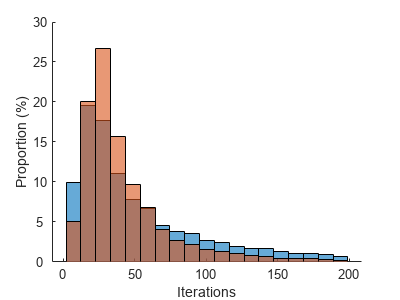

mnw = 51.3695

mw = 42.2855

gmm_white_converged = gmm_white(gmm_white.converged == 1, :);
gmm_not_white_converged = gmm_not_white(gmm_not_white.converged == 1, :);

[mnw, mw] = hist_comp(gmm_white_converged, gmm_not_white_converged, "n_iter", "Iterations")

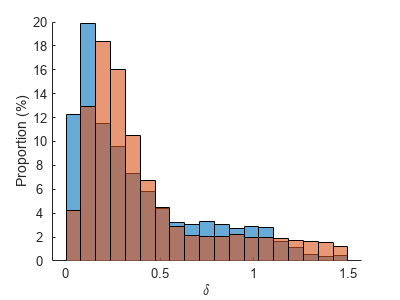

mnw = single
0.3912

mw = single
0.4291

[mnw, mw] = hist_comp(gmm_white_converged, gmm_not_white_converged, "delta", "$\delta$", [0, 1.5])

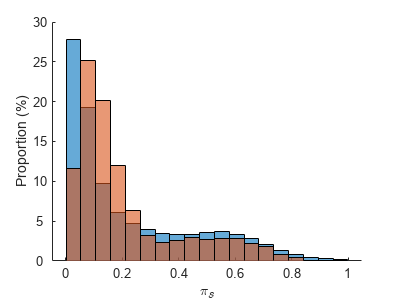

mnw = single
0.2232

mw = single
0.2114

[mnw, mw] = hist_comp(gmm_white_converged, gmm_not_white_converged, "pi_s", "$\pi_s$")

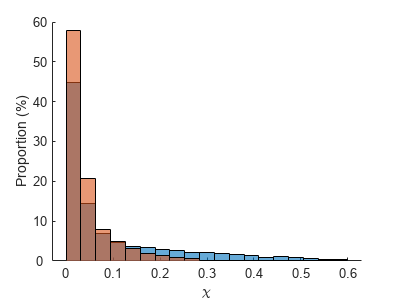

mnw = single
0.0977

mw = single
0.0441

[mnw, mw] = hist_comp(gmm_white_converged, gmm_not_white_converged, "contam", "$\chi$", [0, 0.6])

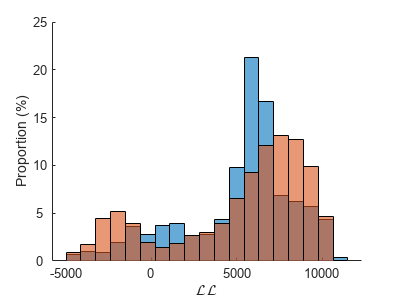

mnw = single
5.1793e+03

mw = single
5.1886e+03

[mnw, mw] = hist_comp(gmm_white_converged, gmm_not_white_converged, "LL", "$\mathcal{LL}$", [-5000, 11500])


beta = sum(gmm_white_converged.pi_s .* (gmm_white_converged.delta/(sum(gmm_white_converged.delta))))

beta = single
0.2977

beta = sum(gmm_not_white_converged.pi_s .* (gmm_not_white_converged.delta/(sum(gmm_not_white_converged.delta))))

beta = single
0.2165

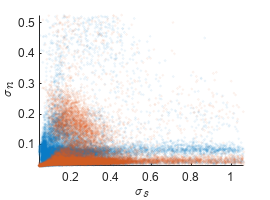

scatter_comp(gmm_white_converged, gmm_not_white_converged,"sigma_s", "sigma_n", "$\sigma_s$", "$\sigma_n$", 1, 1)

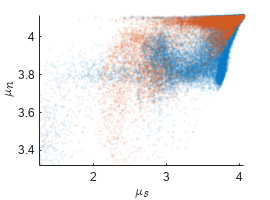

scatter_comp(gmm_white_converged, gmm_not_white_converged,"mu_s", "mu_n", "$\mu_s$", "$\mu_n$", 1, 1)

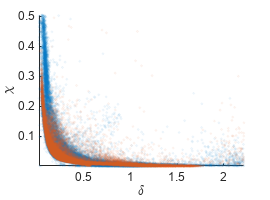

scatter_comp(gmm_white_converged, gmm_not_white_converged,"delta", "contam", "$\delta$", "$\chi$", 1, 5)

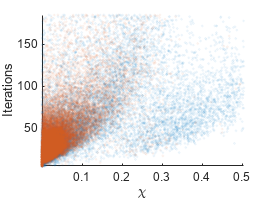

scatter_comp(gmm_white_converged, gmm_not_white_converged,"contam", "n_iter", "$\chi$", "Iterations", 5, 1)

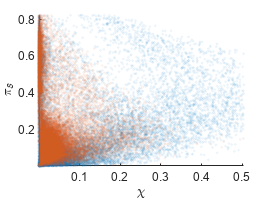

scatter_comp(gmm_white_converged, gmm_not_white_converged,"contam", "pi_s", "$\chi$", "$\pi_s$", 5, 1)

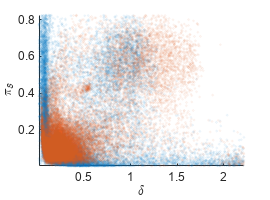

scatter_comp(gmm_white_converged, gmm_not_white_converged,"delta", "pi_s", "$\delta$", "$\pi_s$", 1, 1)